## 0. Initialization

**Cleaning the environment**

clear; close all; clc;

**Installation and import**

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

**Models:**

Models = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'models');
Models = char(java.io.File(Models).getCanonicalPath); % normalize path
addpath(Models);

## 1. Model

This model for Repressilator is already implemented with the name as ``func_elo00``, provided by Prof. Baum, saved in the path for models as above.

Parameters:

% Parameters from supplementary material
% Parameters Elowitz repressilator
beta0 = 0.0012; beta1 = 0.1155;
alpha0 = 5*1e-4; alpha1 = 0.5; k1=0.0058;
klin=[beta0,beta1,beta0,beta1,beta0,beta1,... %beta1: protein production, beta0: protein degradation
 alpha0,alpha1,k1,alpha0,alpha1,k1,alpha0,alpha1,k1];%alpha0, alpha1: mRNA production; k1: mRNA degradation
knonlin=[40,40,40,2,2,2]; %KM:inhibition constants, n: inhibition Hill coefficient
%Initial conditions Elowitz repressilator
s_ini_elo=zeros(1,6);
s_ini_elo(4)=1;

labels = [ 'LacI', 'TetR', 'λ cl', 'LacI mRNA', 'TetR mRNA', 'λ cl mRNA']

labels = 'LacITetRλ clLacI mRNATetR mRNAλ cl mRNA'

## 2. Result reproduction

### Temporal dynamics

Solving the ODE model to observe temporal dynamics

Intial stimulation to stablize the system

tspan = linspace(0, 40900, 40901);
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_elo00_fix(t,x,klin, knonlin), tspan, s_ini_elo, opts);
s_star_2=sol(end,:); %the last point of the simulation is chosen

Plot

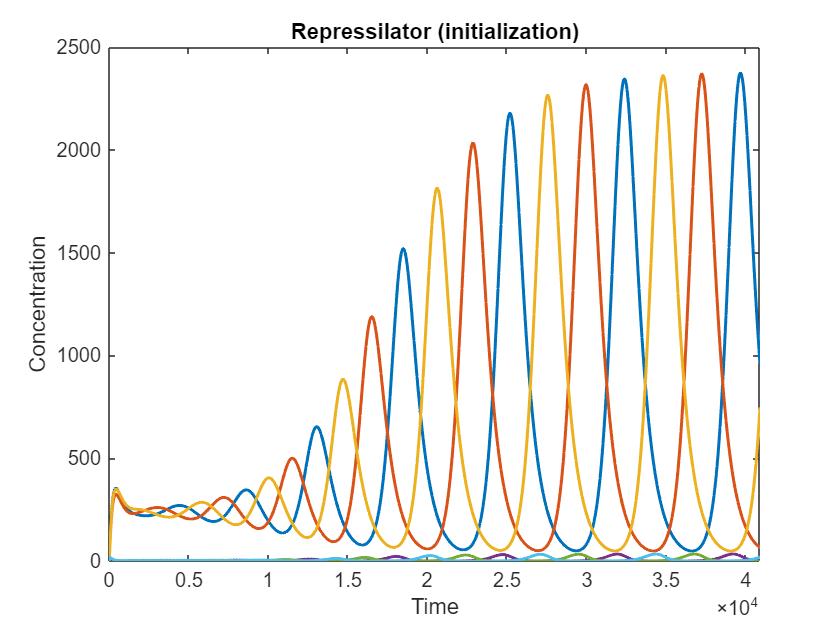

figure;
plot(t, sol, 'LineWidth', 1.5);
%xline(t_perb, '--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('Concentration');
xlim([0,40900]);
% ylim([0,2]);
title('Repressilator (initialization)');

%legend('A','B','Location','eastoutside'); % southeast

Now, when the system have stable trajectories, draw temporal dynamics for t=[0, 50000].

tspan = linspace(0, 50000, 50001);
[t,sol] = ode15s(@(t,x) func_elo00_fix(t,x,klin, knonlin), tspan, s_star_2, opts);

Extract selected variables:

investigate_label = {'TetR', 'λ cl', 'LacI'};
investigate_index = [2, 3, 1];

Plot only selected variables:

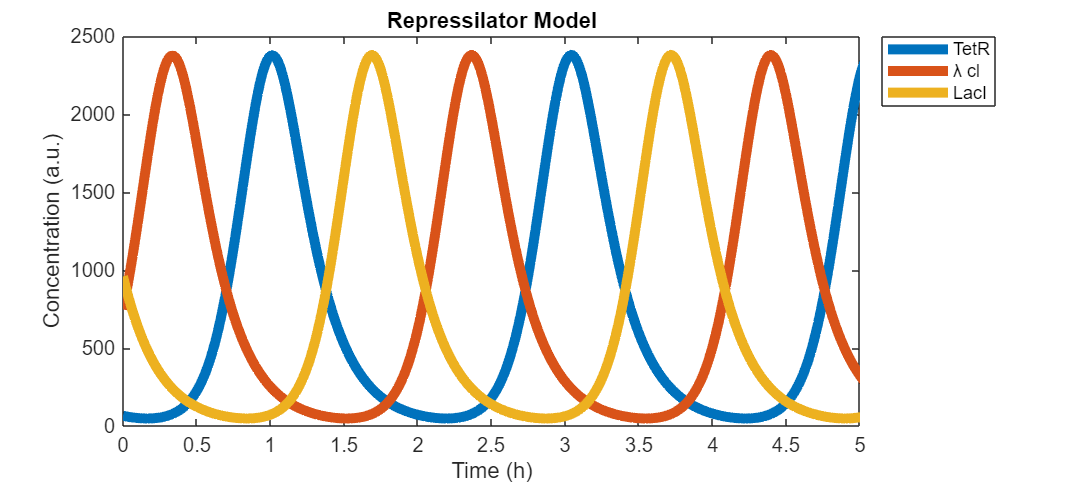

figure('Position',[100 100 900 400]);
hold on
for i = 1:numel(investigate_index)
    plot(t/3600, sol(:, investigate_index(i)), 'LineWidth', 5, ...
        'DisplayName', investigate_label{i});
end
hold off

xlim([0, 5]); %50000/3600
%xticks(0:500:5000);

%ylim([0, 250]);
%yticks(0:50:250);

xlabel('Time (h)');
ylabel('Concentration (a.u.)');
title('Repressilator Model');
legend('Location','northeastoutside');  % similar to Python legend outside
box on

Extract selected variables:

investigate_label = {'TetR mRNA', 'λ cl mRNA', 'LacI mRNA'};
investigate_index = [5, 6, 4];

Plot only selected variables:

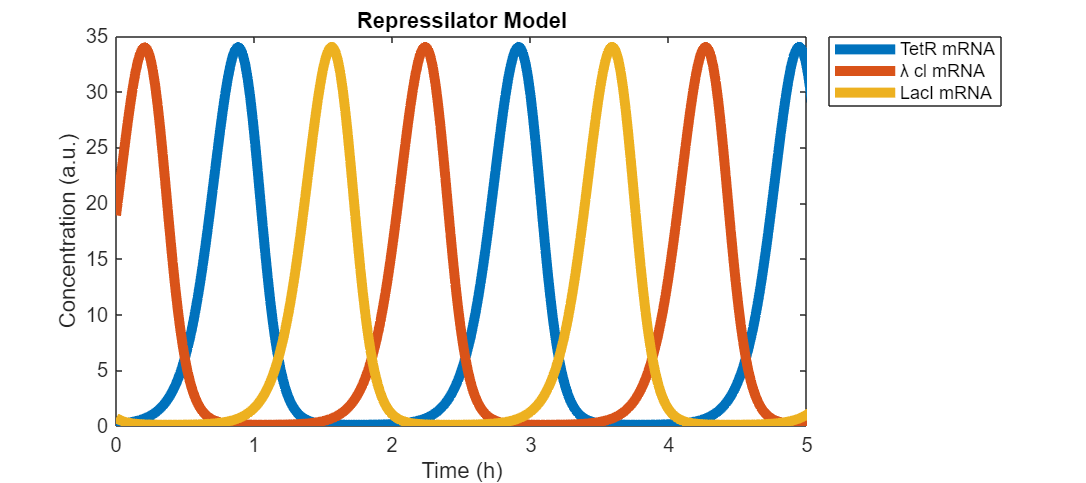

figure('Position',[100 100 900 400]);
hold on
for i = 1:numel(investigate_index)
    plot(t/3600, sol(:, investigate_index(i)), 'LineWidth', 5, ...
        'DisplayName', investigate_label{i});
end
hold off

xlim([0, 5]); %50000/3600
%xticks(0:500:5000);

%ylim([0, 250]);
%yticks(0:50:250);

xlabel('Time (h)');
ylabel('Concentration (a.u.)');
title('Repressilator Model');
legend('Location','northeastoutside');  % similar to Python legend outside
box on

### **Detect loop structures:**

[loop_rep, loop_rep_index, jac_rep, jac_rep_index] =find_loops_vset(@(x)func_elo00_fix(1,x,klin,knonlin),sol',1000);
disp(loop_rep)

    {7×3 table}



### **Loop structures**

disp(loop_rep{1});

          loop           length    sign
    _________________    ______    ____

    {[6 3 4 1 5 2 6]}      6        -1 
    {[          1 1]}      1        -1 
    {[          2 2]}      1        -1 
    {[          3 3]}      1        -1 
    {[          4 4]}      1        -1 
    {[          5 5]}      1        -1 
    {[          6 6]}      1        -1 



disp(loop_summary(loop_rep{1}));

                length_1    length_2    length_3    length_4    length_5    length_6
                ________    ________    ________    ________    ________    ________

    total          6           0           0           0           0           1    
    negative       6           0           0           0           0           1    
    positive       0           0           0           0           0           0    



### **Jacobian matrices:**

j_matrix=numerical_jacobian_complex(@(s)func_elo00_fix(1,s,klin,knonlin),sol(end,:)');
disp(j_matrix);

   -0.0012         0         0    0.1155         0         0
         0   -0.0012         0         0    0.1155         0
         0         0   -0.0012         0         0    0.1155
         0         0   -0.0017   -0.0058         0         0
   -0.0000         0         0         0   -0.0058         0
         0   -0.0001         0         0         0   -0.0058



disp(jac_rep{1});

    -1     0     0     1     0     0
     0    -1     0     0     1     0
     0     0    -1     0     0     1
     0     0    -1    -1     0     0
    -1     0     0     0    -1     0
     0    -1     0     0     0    -1



## Export *.mlx to *.md / *.pdf

path = export("MATLAB/model_7_Repressilator.mlx", "MATLAB/model_7_Repressilator.pdf")

path = 'MATLAB\model_7_Repressilator.pdf'

mdfile = export("MATLAB/model_7_Repressilator.mlx","MATLAB/model_7_Repressilator.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)

mdfile = 'MATLAB\model_7_Repressilator.md'